## Initialize a new wave vortex transform

N0 = 3*2*pi/3600;
L_gm = 1300;
N2 = @(z) N0*N0*exp(2*z/L_gm);
wvt = WVTransformHydrostatic([100e3, 100e3, 4000],[64, 64, 65], N2=N2,latitude=30);

The operation nonlinearFlux with variables {Fp,Fm,F0,} has been removed and the operation Boussinesq with variables {Fp,Fm,F0,} has been added.


## Add an internal wave, write to file

[omega,k,l]=wvt.initWithWaveModes(k=5,l=0,j=2,phi=0,u=0.2,sign=1);
wvt.writeToFile('Tutorial_002.nc');

In addition to the NetCDF file, a .mat sidecar file was created at the same path.


Now clear all variables...

clear all;

And then initialize the WVT directly from file.

wvt = WVTransform.waveVortexTransformFromFile('Tutorial_002.nc');

The operation nonlinearFlux with variables {Fp,Fm,F0,} has been removed and the operation Boussinesq with variables {Fp,Fm,F0,} has been added.
WVTransformHydrostatic initialized from Ap, Am, A0.


wvt =   WVTransformHydrostatic with properties:

                    rhobar: [65×1 double]
                        N2: [65×1 double]
                     dLnN2: [65×1 double]
               rhoFunction: [Inf×1 chebfun]
                N2Function: @(z)N0*N0*exp(2*z/L_gm)
             dLnN2Function: []
             internalModes: [1×1 InternalModesWKBSpectral]
                     PFinv: [65×64 double]
                     QGinv: [65×64 double]
                        PF: [64×65 double]
                        QG: [64×65 double]
                         h: [1×1×64 double]
                         P: [1×1×64 double]
                         Q: [1×1×64 double]
                   zInterp: []
               PFinvInterp: []
               QGinvInterp: []
             Apm_TE_factor: [64×64×64 double]
             A0_HKE_factor: [64×64×64 double]
              A0_PE_factor: [64×64×64 double]
              A0_TE_facto

## Prove the data is still there and make a few plots

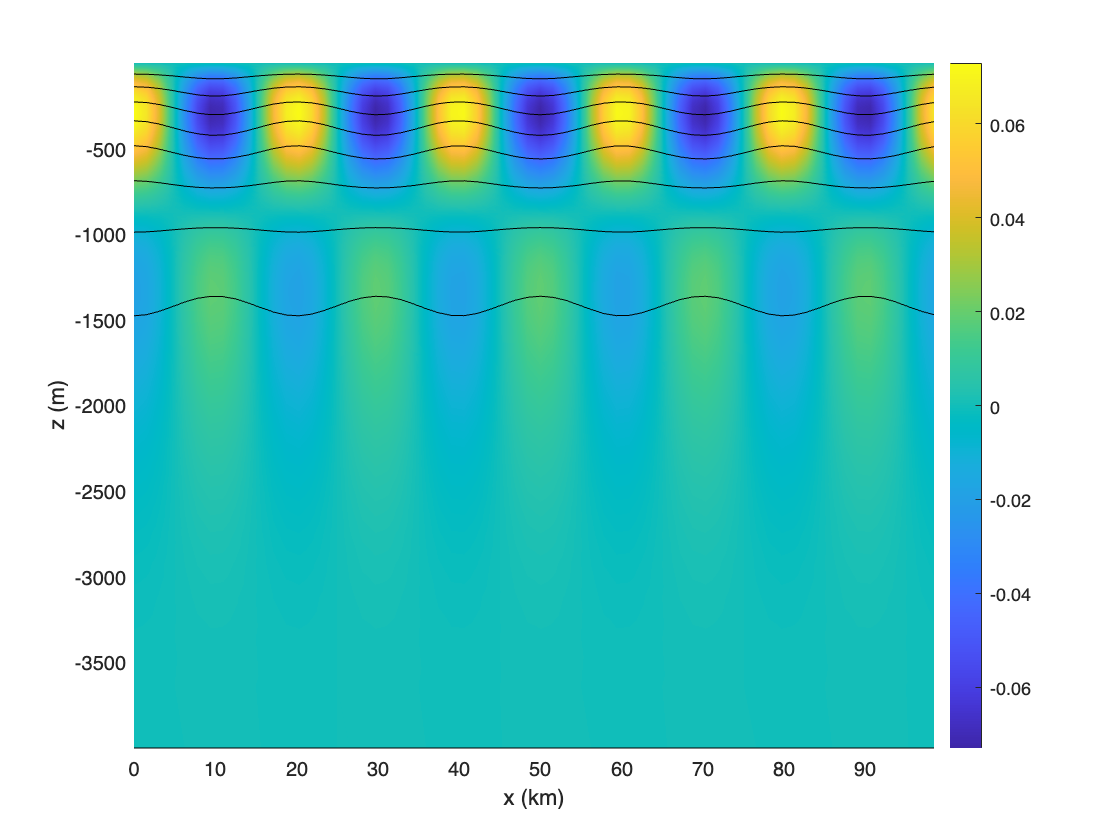

rho = wvt.rho_prime;
rho_total = wvt.rho_total;
figure
pcolor(wvt.x/1000,wvt.z,squeeze(rho(:,1,:)).'); colorbar; clim([min(rho(:)),max(rho(:))]), shading interp, hold on
contour(wvt.x/1000,wvt.z,squeeze(rho_total(:,1,:)).',linspace(min(rho_total(:)),max(rho_total(:)),10),'k','LineWidth',0.5);
xlabel('x (km)'), ylabel('z (m)')